# Filtry dla radia FM

Hamming or Blackman

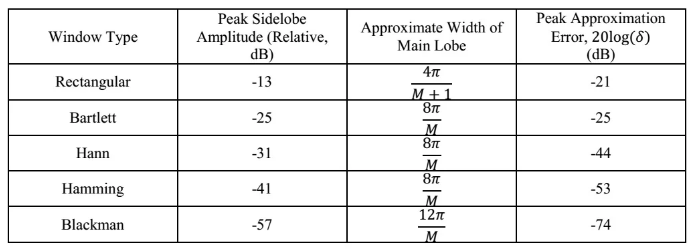

Filtr I

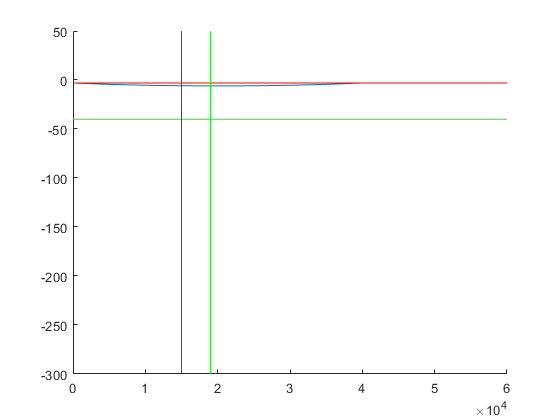

%fs = 32e5; 
fs = 80e3;
f2w = @(f) 2*pi*(f/fs);
w2f = @(w) w*fs/(2*pi);

fleft = 0; fright=5e3;
df = fright - fleft;

% transition band:
dw = 2*pi*(df/fs);

% eq to get lobe width approx
widthEq = @(w) 12*pi/w;

M = round(widthEq(dw));

% bandwith
wp=f2w(15e3);ws=f2w(19e3);

%wc = (wp+ws)/2;
%wc = f2w(15e3);

% filter one
%h1 = fir1(M,(wc)/(f2w(fs)),'low',blackman(M+1));
%M = 128;
%h1 = fir1(M,15e3/fs,'low',blackman(M+1));
h1 = customFir(M,15e3,15e3/2,fs, @blackman);

% plot filter one 
figure
[h1M,f1M] = freqz(h1,1,M,fs); %0:0.05:fs-0.05
%[h1M,f1M] = freqz(h1,1,0:0.05:fs-0.05,fs);
figure
hold all
plot(f1M,20*log10(abs(h1M)))
plot([0 60e3],[-3 -3],'r-'); % -3dB
plot([0 60e3],[-40 -40],'g-'); % -40dB
plot([15e3 15e3],[-300 50],'r-'); % 15kHz
plot([19e3 19e3],[-300 50],'g-'); % 19kHz

%xlim([0 60e3])

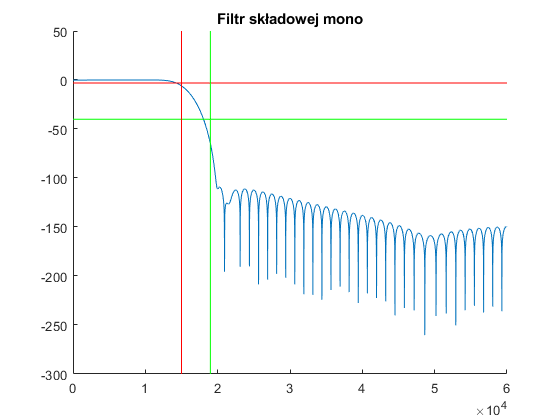


% by design
N=128;bwSERV = 80e3;
b = fir1(N,[30/bwSERV 15e3/bwSERV],blackmanharris(N+1));
[h,f] = freqz(b,1,0.1:0.05:80e3,80e3);
figure
hold all;
plot(2*f,20*log10(abs(h)));
plot([0 60e3],[-3 -3],'r-'); % -3dB
plot([0 60e3],[-40 -40],'g-'); % -40dB
plot([15e3 15e3],[-300 50],'r-'); % 15kHz
plot([19e3 19e3],[-300 50],'g-'); % 19kHz
title('Filtr składowej mono');
xlim([0 60e3]);

%custom func

function [H F] = customFir(M, dr, fc, fs, func)
    
    n = 0:M;

    % hertz to rad and start, stop rad freq
    wleft   = 2*pi*(fc-dr/2)/fs;
    wright  = 2*pi*(fc+dr/2)/fs;
    %wcenter = 2*pi*fc/fs;
    wcenter = M/2;
    
    % substr of two lowpass filters with time shift:
    hd = (wright/pi)*sinc(wright*(n-wcenter)/pi) - (wleft/pi)*sinc(wleft*(n-wcenter)/pi);
    
    %plot(1:M+1,hd)
    
    h = func(M+1)'.*hd;
    
    [H F] = freqz(h,1,M,fs);
end